# Root Loci - Exercises

The examples in this live script describe how to solve, by exploiting root loci:

(a) closed-loop stability analysis problems, identifying critical values of the gain constant, which allow one to discriminate between asymptotic closed-loop stability, closed-loop instability and marginal stability;

b) simple controller design problems, modifying the controller's initial transfer function by adding a zero, a pole, or both, to ensure asymptotic closed-loop stability.

## Exercise 1: A High Positive Gain Will Stabilise the Closed-Loop System

Consider the following block diagram:

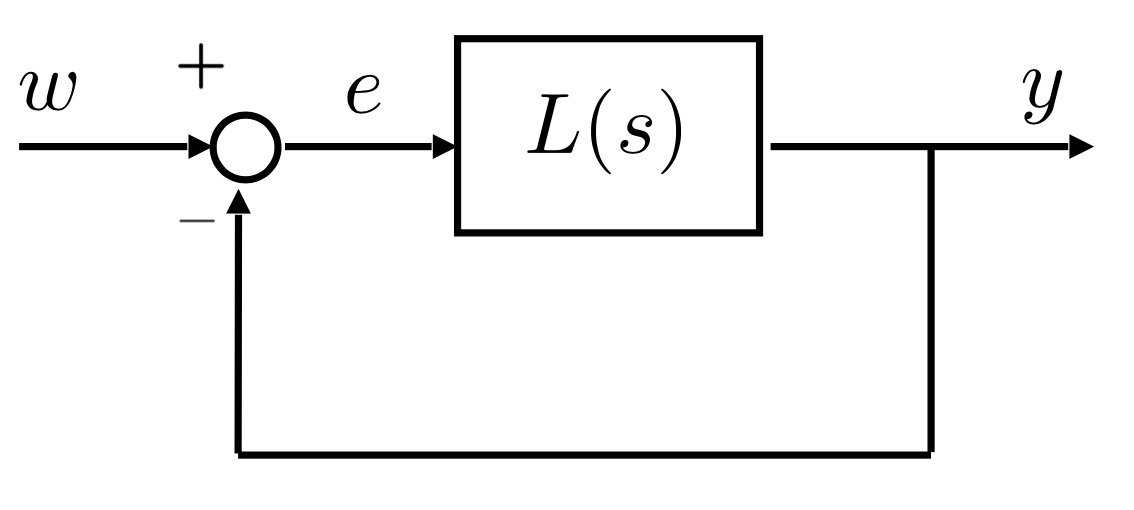

where $L(s)$ is the transfer function


$$L(s) = \varrho \frac{s+1}{s\,(s-2)\,(s+4)}\;, \varrho \in \mathbb{R}$$


- Is it possible to stabilise the system?

- Analyse the direct and inverse roots locus and determine (if possible) a range of gain values such that closed-loop asymptotic stability for the system is guaranteed.

### The Open-Loop Transfer Function

clear variables

s = tf('s');

Ls = (s+1)/(s * (s-2) * (s+4));

zLs = zero(Ls)

zLs = -1

m = numel(zLs); % degree of the polynomial at the numerator in L(s)

pLs = pole(Ls)

pLs =      0
    -4
     2


n = numel(pLs); % degree of the polynomial at the denominator in L(s)

### Roots Loci Centroid and Asymptotes

#### The Centroid

Given


$$L(s) = \varrho\,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} ,\; \varrho \in \mathbb{R},\; m < n$$


the center of the asymptotes (named **centroid**) is 


$$x_a = \frac{1}{n-m} \left[ \sum_{j=1}^{m} z_j - \sum_{i=1}^{n} p_i \right]$$


x_a = (1/(n-m)) * (sum(-zLs) + sum(pLs))

x_a = -0.5000

#### The Direct Root Locus Asymptotes

The $(n-m)$ **asymptotes** of the **Direct** **RL** form the following angles with the real axis


$$\psi_a = \frac{(2k+1)\cdot 180^{\circ}}{n-m},\;k=0,\,1,\,\ldots ,\, n-m-1$$


k = (0:n-m-1);
theta_a_DL = (180/(n-m))*(2.*k+1)

theta_a_DL =     90   270


#### The Inverse Root Locus Asymptotes

The $(n-m)$ **asymptotes** of the Inverse **RL** form the following angles with the real axis


$$\psi_a = \frac{2k\cdot 180^{\circ}}{n-m},\;k=0,\,1,\,\ldots ,\, n-m-1$$


k = (0:n-m-1);
theta_a_IL = (180/(n-m))*(2.*k)

theta_a_IL =      0   180


### Critical Points

#### **Breakaway/Break-In Points on the Direct Locus**

crPoints_RL = DetermineCriticalPointsRL(Ls)

crPoints_RL = 0.8356


cP_DLset = checkCriticPointsDL(crPoints_RL, Ls)

cP_DLset = 0.8356

#### **Breakaway/Break-In Points on the Inverse Locus**

cP_ILset = checkCriticPointsIL(crPoints_RL, Ls)

cP_ILset =
     []


### The Direct Root Locus

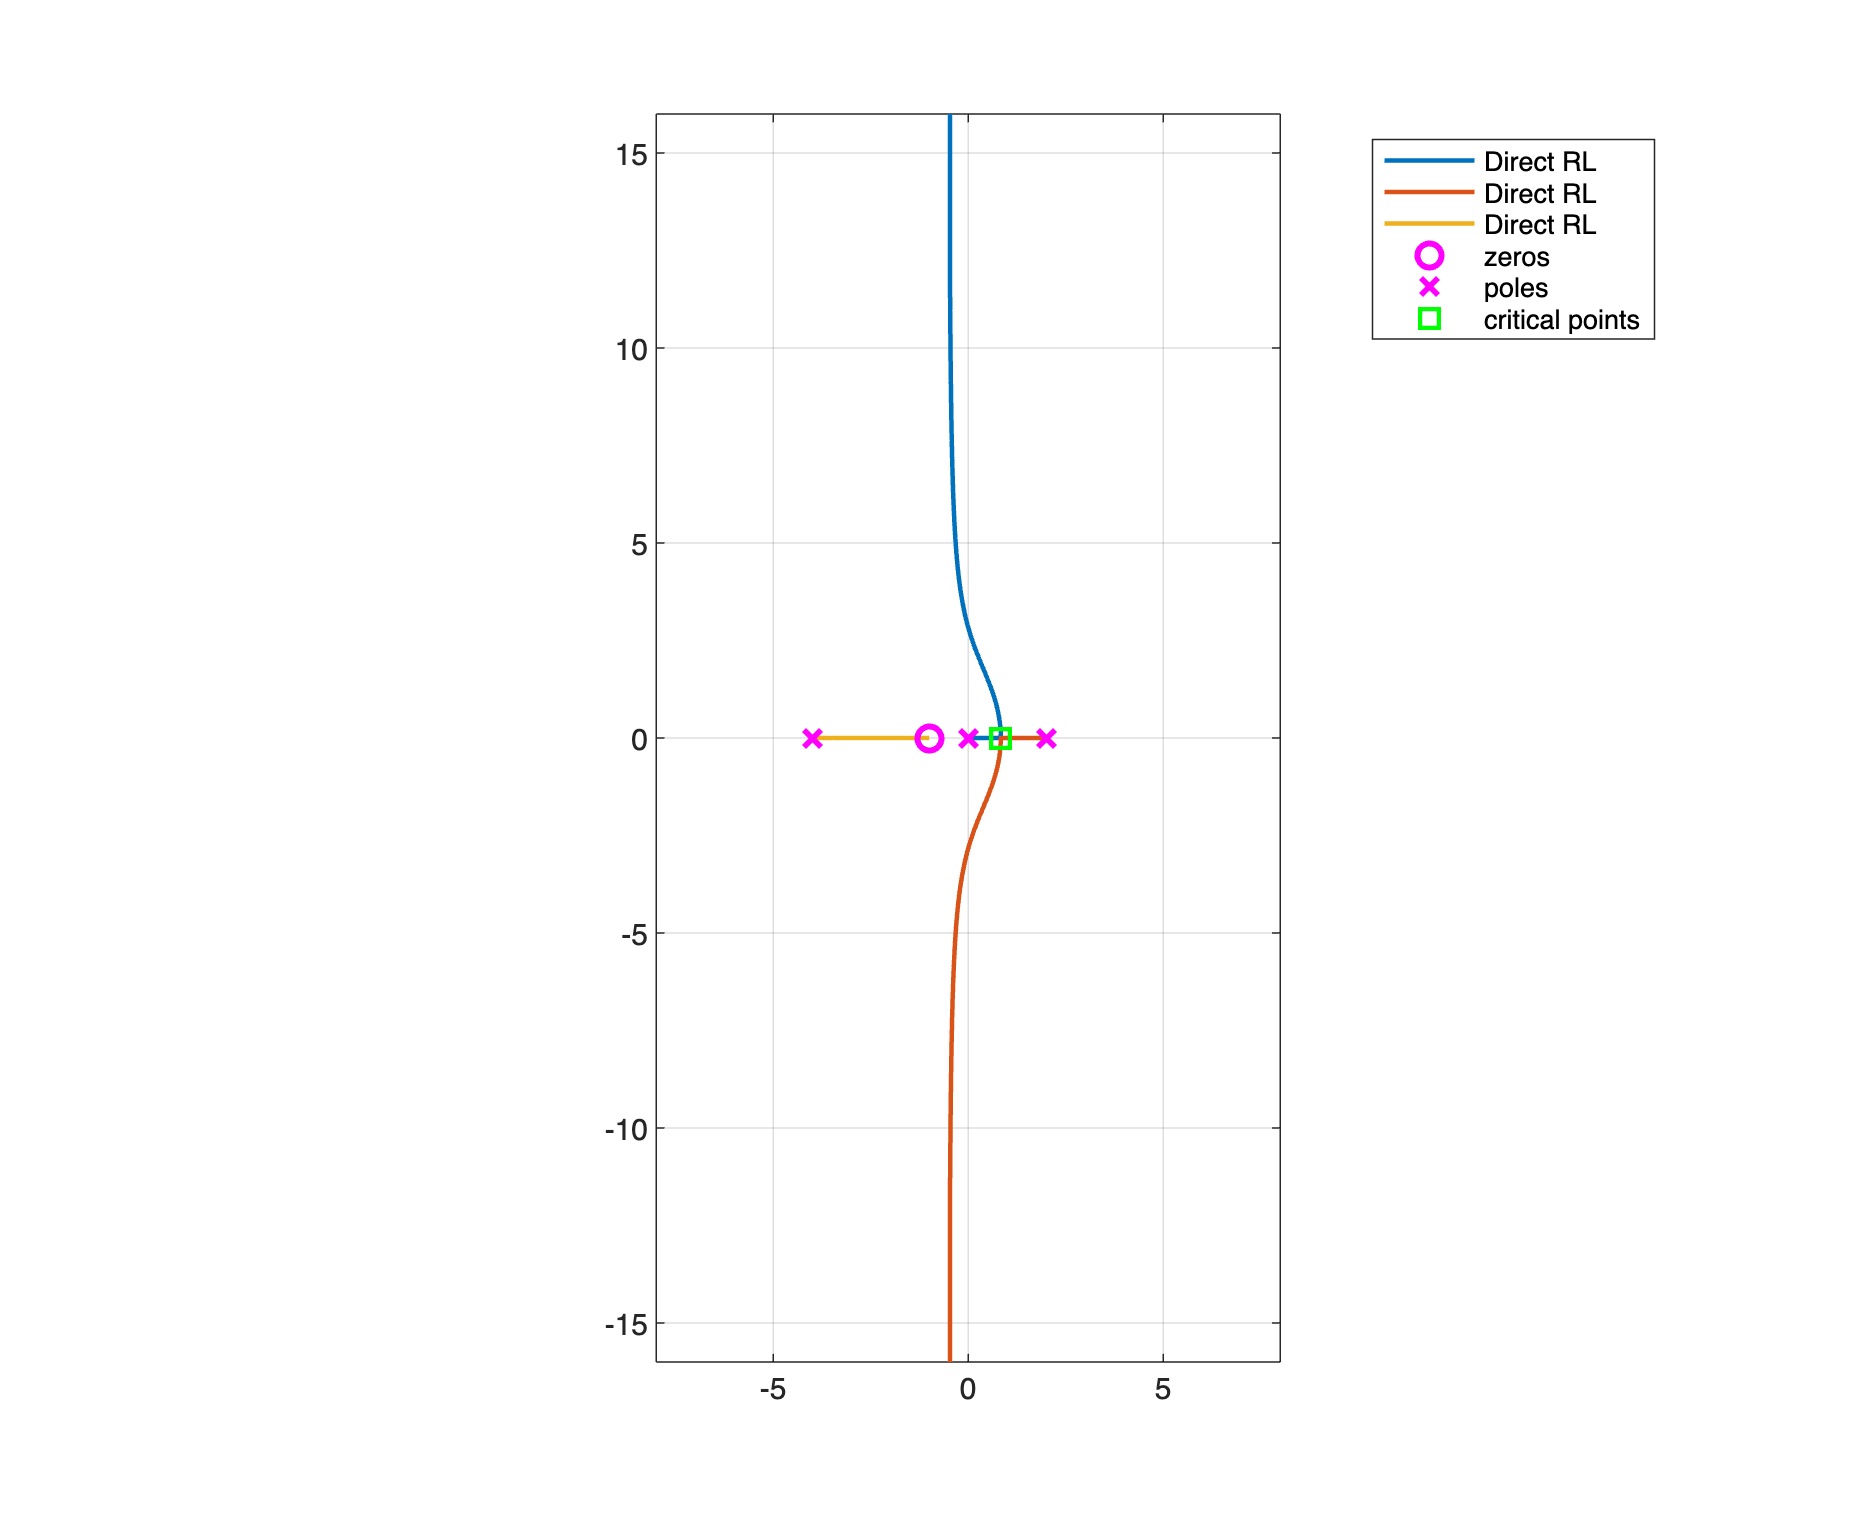

DRL_Ls = rlocus(Ls); 
% note the structure of DRL_Ls: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
h_rld1 = zeros(n, 1); % let's preallocate the data array
for k=1:n
    h_rld1(k,1) = plot( real(DRL_Ls(k,:)),imag(DRL_Ls(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s_B = plot(real(zLs),imag(zLs),'mo', ...
    real(pLs),imag(pLs),'mx', ...
    real(cP_DLset), imag(cP_DLset), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

grid on; hold off; axis equal;
axis([-8,8,-16, 16]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k
legend([LocusLeg, {'zeros','poles','critical points'}], 'Location', 'best')

#### Discussion

- For (positive) gain values close to zero, the closed-loop system is unstable. 

- However, if the gain becomes high enough, then (as can be seen from the root locus plot) the closed-loop poles enter the left half-plane and stay there, so the closed-loop system will be asymptotically stable as long as it chooses a high enough (positive) value for the gain.

#### The Critical Gain

- Determine the** gain's critical value**, such that for a gain value lower than the critical one, the closed-loop system is unstable. In contrast, for a gain value higher than the critical one, the closed-loop system will be asymptotically stable.

- Analysing the Root Locus, the **critical** **gain** **values** **correspond** to the values of the gain, for which **some** **branches** of the Direct Root Locus **cross** the **imaginary** **axis**.

- Alternatively,  you can compute these critical values by analysing the **terms** in the **first** **column** of the **Routh** **table**, looking for changes in the sign of those terms.

**First approach**: let's use the MATLAB command `rlocfind`

Select a point in the graphics window


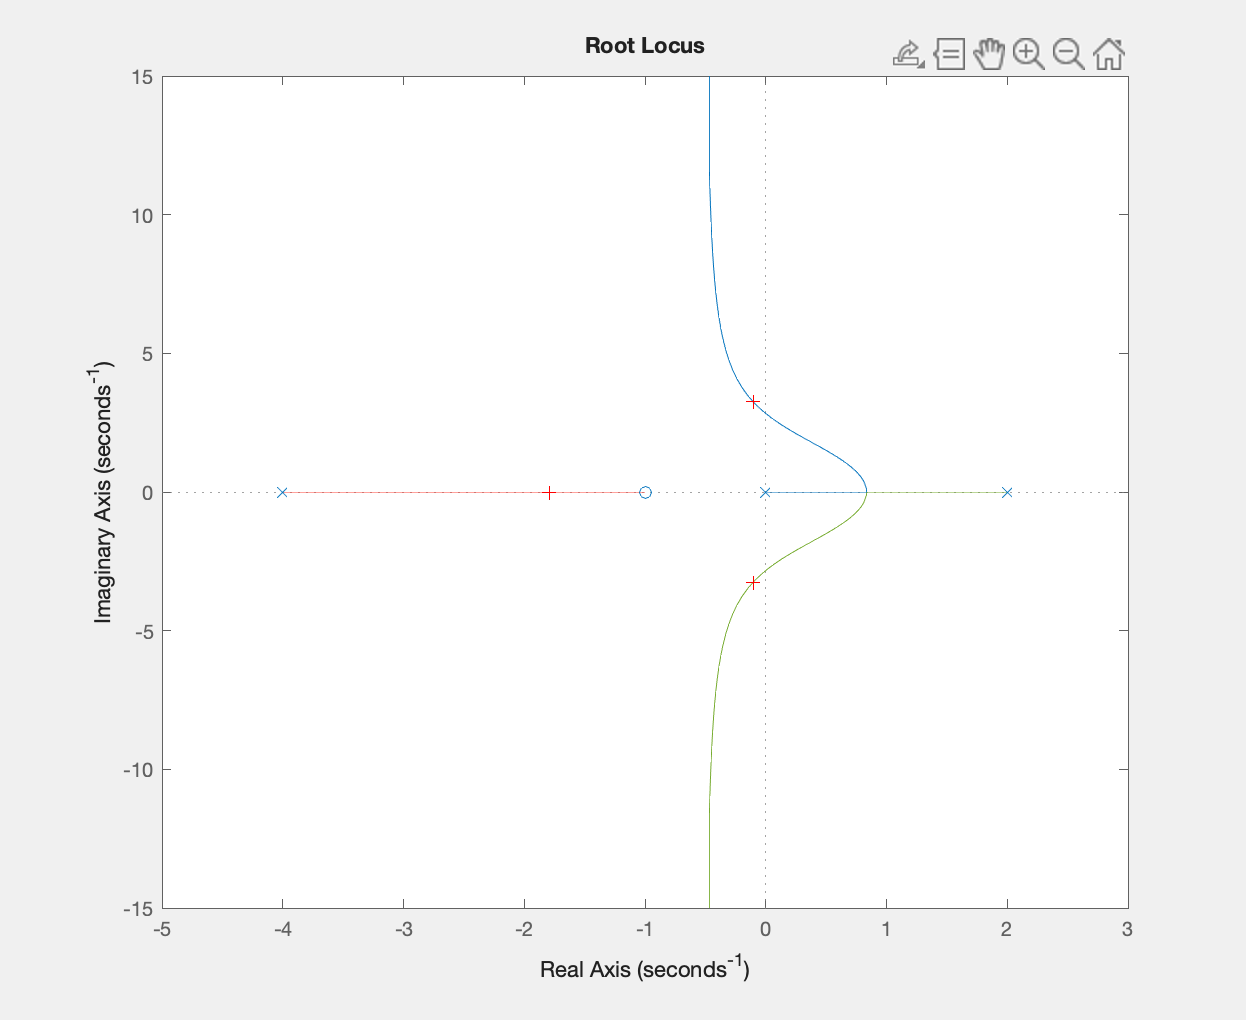

selected_point = -0.0683 + 3.2632i

KK = 18.9861

cc_poles =   -0.1052 + 3.2555i
  -0.1052 - 3.2555i
  -1.7895 + 0.0000i


[KK, cc_poles] = rlocfind(Ls)

For $\varrho \gg \text{KK}$ th closed-loop system results asymptotically stable.

**Second approach**: let's use the **Routh** **table**:

Given


$$L(s) = \varrho \frac{s+1}{s\,(s-2)\,(s+4)}\;, \varrho \in \mathbb{R},\; \varrho >0$$


the closed-loop polynomial is


$$p\left(s,\,\varrho \right) = s\,\left(s-2\right)\, \left(s+4 \right) + \varrho \,\left(s+1 \right) = s^3+2\,s^2+\left(\varrho - 8 \right)\,s + \varrho$$


The corresponding Routh table is:


$$\begin{array}{c|cc}
3 & 1& \varrho-8 \\
2 & 2 & \varrho \\
1 & \varrho - 16 & \\
0 & \varrho
\end{array}$$


Thus, the sign of the terms in the first column of the Routh table depends on the gain $\varrho$ as follows


$$\left\{ \begin{array}{rcll}
1 &>&0 &\forall \varrho>0 \\
2 &>&0 &\forall \varrho>0 \\
\varrho-16 &\ge& 0 & \Longrightarrow \; \varrho \ge 16 \\
\varrho & >& 0 & \forall \varrho>0
\end{array} \right. \qquad \Longrightarrow \qquad $$
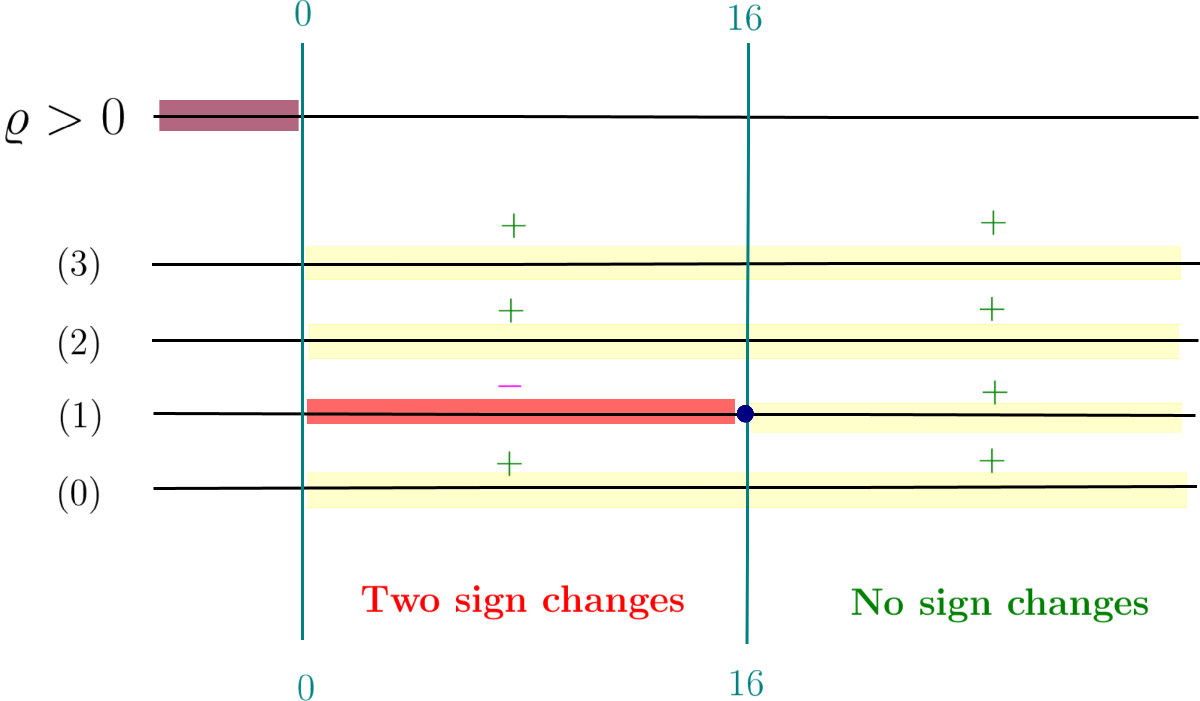

The **critical** **gain** **value** is $\bar \varrho = 16$:

-  for $\bar \varrho > 16$, the closed-loop system is **asymptotically** **stable**,

-  whereas for $\bar \varrho < 16$, the system becomes **unstable**. 

- For $\bar \varrho = 16$, the closed-loop polynomial assumes the expression $p(s,\,\bar \varrho) = s^3+2\,s^2+8\,s+16 = (s+2)\,(s^2+8)$. Thus, the system is **marginally** **stable**.

### The Inverse Root Locus

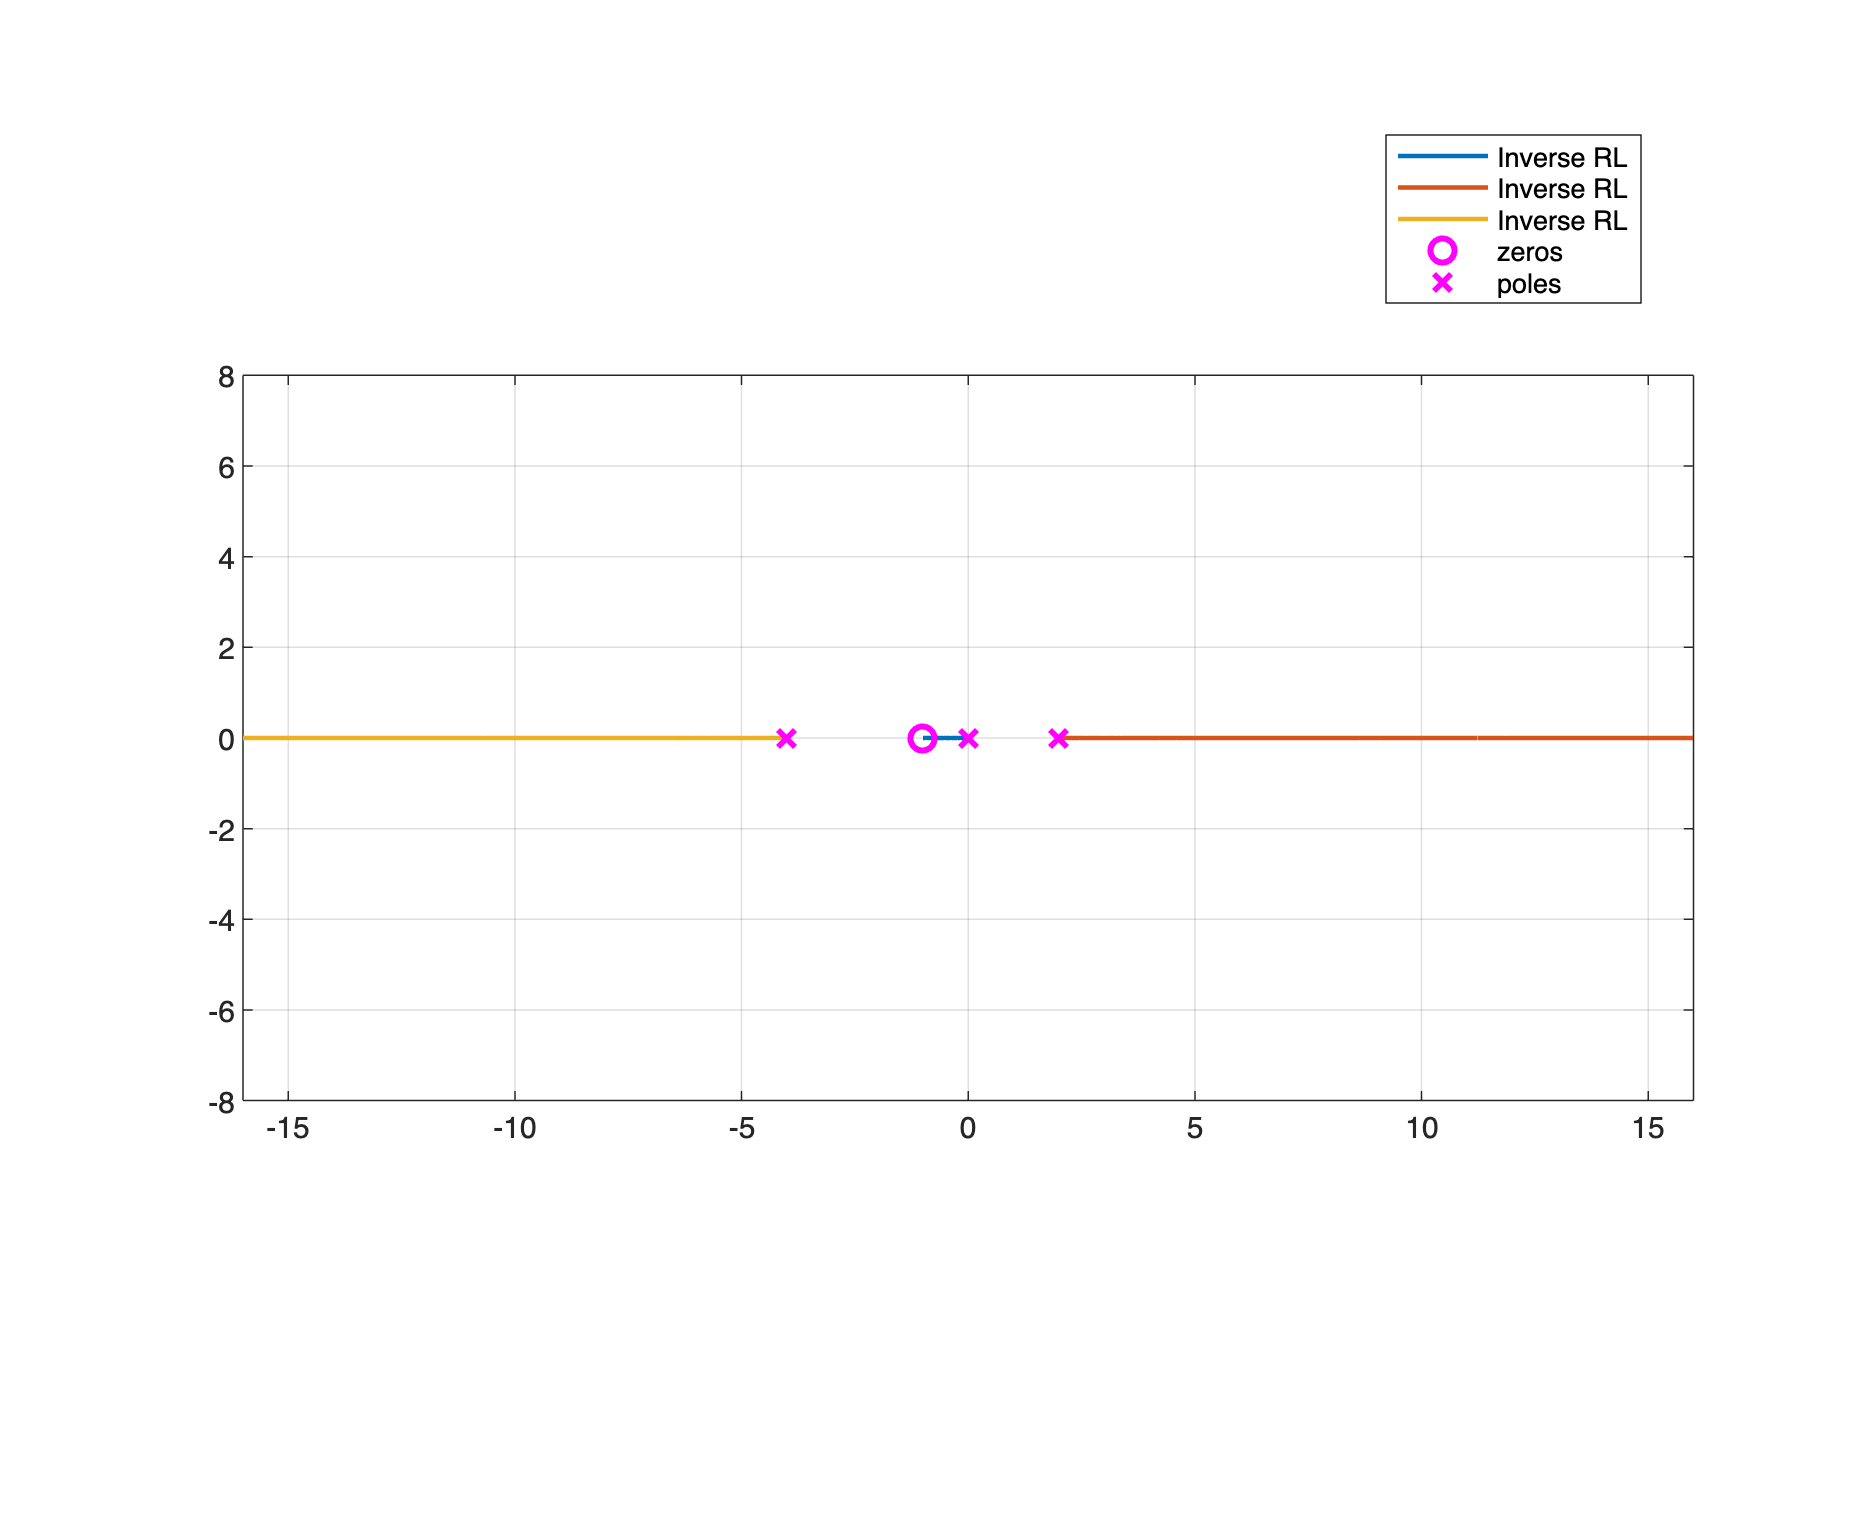

IRL_Ls = rlocus(-Ls); % NOTE the "-" sign! With this trick, we can determine 
                      % the Inverse Root Locus as a "masked" Direct Locus

% note the structure of IRL_Ls: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
h_rli1 = zeros(n, 1); % let's preallocate the data array
for k=1:n
    h_rli1(k,1) = plot( real(IRL_Ls(k,:)),imag(IRL_Ls(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
if isempty(cP_ILset)
    h_s_B = plot(real(zLs),imag(zLs),'mo', ...
        real(pLs),imag(pLs),'mx', ...
        'MarkerSize',8, 'LineWidth',2);
else
    h_s_B = plot(real(zLs),imag(zLs),'mo', ...
        real(pLs),imag(pLs),'mx', ...
        real(cP_ILset), imag(cP_ILset), 'gs', ...
        'MarkerSize',8, 'LineWidth',2);
end % if

grid on; hold off; axis equal;
axis([-16,16,-8, 8]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Inverse RL';
end % for k
if isempty(cP_ILset)
    legend([LocusLeg, {'zeros','poles'}], 'Location', 'best')
else
    legend([LocusLeg, {'zeros','poles','critical points'}], 'Location', 'best')
end % if

#### Discussion

- For negative gain values, the closed-loop system is **always** **unstable**. Note the Inverse RL branch in the Right Half Plane, starting from the pole $p_1 = +2$ and going to $+\infty$.

## Exercise 2: Stabilise the Closed-Loop System and Fine-Tune the Gain

Consider the following block diagram:

where $L(s)$ is the transfer function


$$L(s) = \varrho \frac{(s+1)^2}{(s-1)^3}\;, \varrho \in \mathbb{R}, \; \varrho >0$$


- Is it possible to stabilise the closed-loop system?

- Analyse the direct root locus and determine (if possible) a range of gain values such that closed-loop asymptotic stability for the system is guaranteed.

- Finally, analyse the poles and the step-response settling time when $\varrho = 4,\, 40,\, 400$.

### The Open-Loop Transfer Function

clear variables

s = tf('s');

Ls = ((s+1)^2)/((s-1)^3);

zLs = zero(Ls)

zLs =     -1
    -1


m = numel(zLs); % degree of the polynomial at the numerator in L(s)

pLs = pole(Ls)

pLs =    1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i


n = numel(pLs); % degree of the polynomial at the denominator in L(s)

### Roots Loci Centroid and Asymptotes

#### The Centroid

Given


$$L(s) = \varrho\,\frac{\prod_{j=1}^{m} (s+z_j)}{\prod_{i=1}^{n} (s+p_i)} ,\; \varrho \in \mathbb{R},\; m < n$$


the center of the asymptotes (named **centroid**) is 


$$x_a = \frac{1}{n-m} \left[ \sum_{j=1}^{m} z_j - \sum_{i=1}^{n} p_i \right]$$


x_a = (1/(n-m)) * (sum(-zLs) + sum(pLs))

x_a = 5.0000

**Note:** the position of the centroid is irrelevant this time. 

#### The Direct Root Locus Asymptotes

The $(n-m)$ **asymptotes** of the **Direct** **RL** form the following angles with the real axis


$$\psi_a = \frac{(2k+1)\cdot 180^{\circ}}{n-m},\;k=0,\,1,\,\ldots ,\, n-m-1$$


k = (0:n-m-1);
theta_a_DL = (180/(n-m))*(2.*k+1)

theta_a_DL = 180

**Note **the angle of the asymptote: the closed-loop system is asymptotically stable if you choose a very high positive gain value. With such a choice, you obtain two poles close enough to the open-loop zeros, and the third pole will lie on the asymptote.

### Critical Points

#### **Breakaway/Break-In Points on the Direct Locus**

crPoints_RL = DetermineCriticalPointsRL(Ls)

crPoints_RL =   -5.0000 + 0.0000i
  -1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i



cP_DLset = checkCriticPointsDL(crPoints_RL, Ls)

cP_DLset =   -5.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i
  -1.0000 + 0.0000i


### The Direct Root Locus

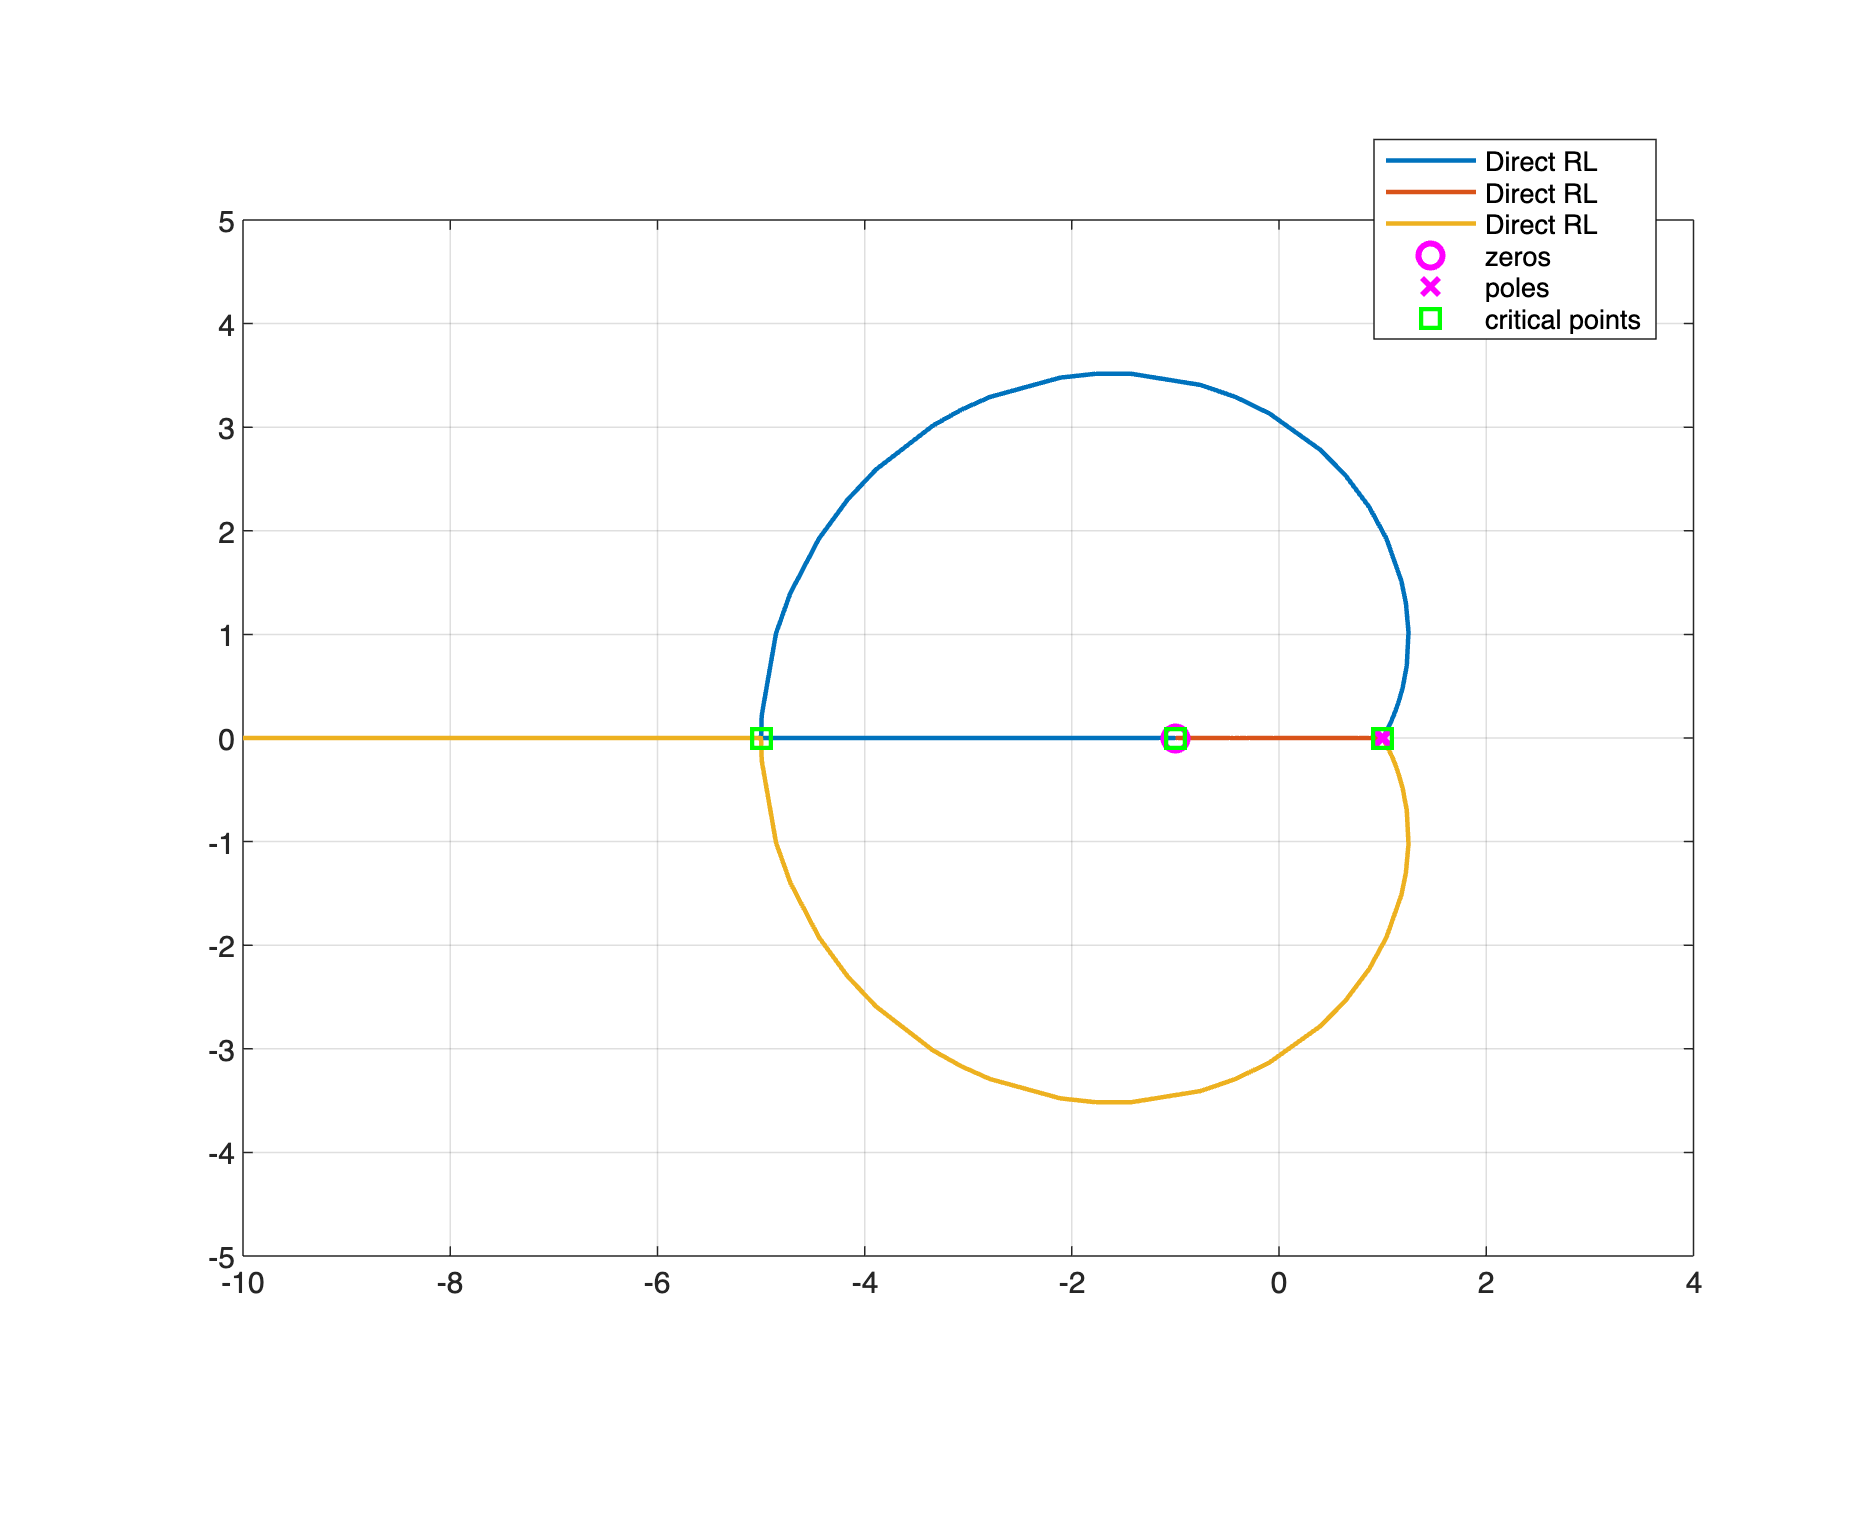

DRL_Ls = rlocus(Ls); 
% note the structure of DRL_Ls: array(n, p)
% where n <--> number of branches (i.e. the degree of the polynomial at
%              denominator)
%       p <--> number of points (closed-loop poles) belonging to each
%              branch, i.e. number of values fo the gain rho used to
%              determine the Direct Locus
figure('Units','centimeters','Position',[0.1, 0.1, 22, 18]);
% the Direct RL
h_rld1 = zeros(n, 1); % let's preallocate the data array
for k=1:n
    h_rld1(k,1) = plot( real(DRL_Ls(k,:)),imag(DRL_Ls(k,:)),'LineWidth',1.5 );
    hold on;
end % for k

% zeros & poles and then singular points
h_s_B = plot(real(zLs),imag(zLs),'mo', ...
    real(pLs),imag(pLs),'mx', ...
    real(cP_DLset), imag(cP_DLset), 'gs', ...
    'MarkerSize',8, 'LineWidth',2);

grid on; hold off; axis equal;
axis([-10,4,-5, 5]); 
LocusLeg = cell(1,n);
for k=1:n
    LocusLeg{1,k} = 'Direct RL';
end % for k
legend([LocusLeg, {'zeros','poles','critical points'}], 'Location', 'best')

#### Discussion

- For (positive) gain values close to zero, the closed-loop system is unstable. 

- However, if the gain becomes high enough, then (as can be seen from the root locus plot) the closed-loop poles enter the left half-plane and stay there, so the closed-loop system will be asymptotically stable as long as it chooses a high enough (positive) value for the gain.

#### The Critical Gain

- Determine the** gain's critical value**, such that for a gain value lower than the critical one, the closed-loop system is unstable. In contrast, for a gain value higher than the critical one, the closed-loop system will be asymptotically stable.

- Analysing the Root Locus, the **critical** **gain** **values** **correspond** to the values of the gain, for which **some** **branches** of the Direct Root Locus **cross** the **imaginary** **axis**.

- Alternatively,  you can compute these critical values by analysing the **terms** in the **first** **column** of the **Routh** **table**, looking for changes in the sign of those terms.

**First approach**: let's use the MATLAB command `rlocfind`

Select a point in the graphics window


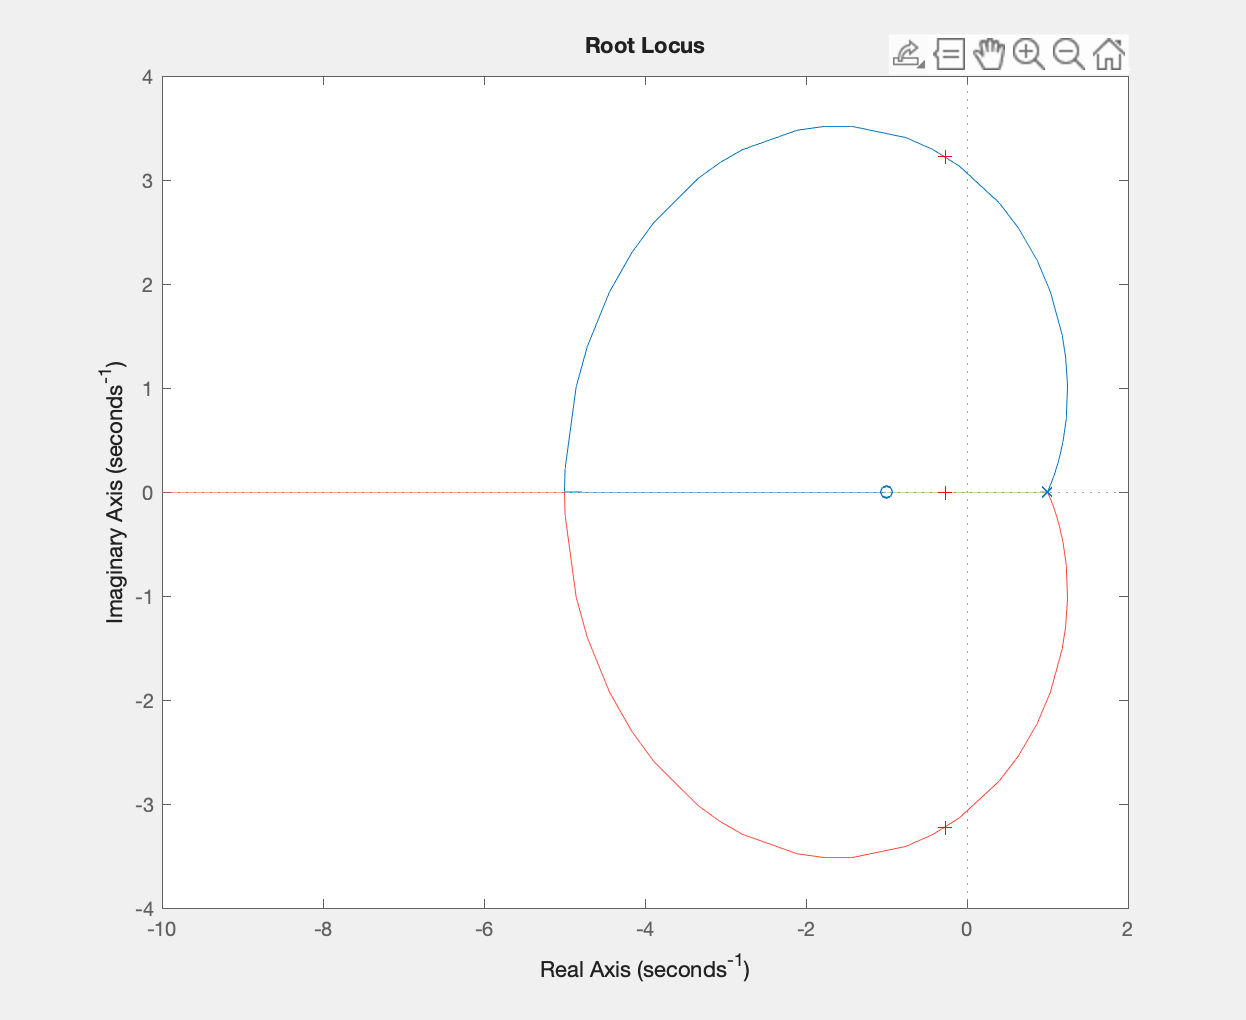

selected_point = -0.2671 + 3.2163i

KK = 3.7963

cc_poles =   -0.2644 + 3.2220i
  -0.2644 - 3.2220i
  -0.2676 + 0.0000i


[KK, cc_poles] = rlocfind(Ls)

For $\varrho \gg \text{KK}$ th closed-loop system results asymptotically stable.

**Second approach**: let's use the **Routh** **table**:

Given


$$L(s) = \varrho \frac{(s+1)^2}{(s-1)^3}\;, \varrho \in \mathbb{R}, \; \varrho >0$$


the closed-loop polynomial is


$$p\left(s,\,\varrho \right) = (s-1)^3+\varrho\,(s+1)^2 = s^3+(\varrho-3)\,s^2+(2\varrho+3)\,s+(\varrho-1)$$


**Verify**, using the Routh table, that the critical value $\bar \varrho$ is: $\bar \varrho = 1+\sqrt{5}$.

Let's consider the assigned set of $\varrho$ values, visualise the corresponding closed-loop poles on the Direct Root Locus and investigate about the performance of the closed-loop system corresponding to each $\varrho$ value:

rhoSET = [4, 40, 400]; %  values for the gain rho

closedLoopPoles = rlocus(Ls, rhoSET);


#### Closed-Loop Performance Analysis

Let's determine the open-loop and the closed-loop transfer functions corresponding to each $\varrho$ value:

r = numel(rhoSET);
OL0_tf = cell(r, 1); % to store the Open-Loop TFs

CL0_tf = cell(r, 1); % to store the Closed-Loop TFs

for i=1:r
    OL0_tf{i} = rhoSET(i)*Ls;

    CL0_tf{i} = feedback(OL0_tf{i}, 1, -1);
end % for i

Now, let's determine the performance for each transfer function.

STABmargins0 = cell(r, 1);
STEPperformance0 =  cell(r, 1);
CLpoles0 = cell(r, 1);

tSET = (0:1e-3:6); % a set of time instants, used to obtain 
                    % an accurate estimation of the settling time etc.
                    % by applying the stepinfo() function

for ijk = 1:r
    [GmVAL,PmVAL,Wcg,Wcp] = margin(OL0_tf{ijk} );
    STABmargins0{ijk} = struct('Gm', GmVAL, ...
                               'GainFreq', Wcg, ...
                               'Pm', PmVAL, ...
                               'PhaseFreq', Wcp);
    CLpoles0{ijk} = pole(CL0_tf{ijk});
    [ySTEP, tSTEP] = step(CL0_tf{ijk},tSET);
    res = stepinfo(ySTEP, tSTEP,  'SettlingTimeThreshold',0.01);
    STEPperformance0{ijk} = struct('RiseT', res.RiseTime, ...
                                   'SettlingT', res.SettlingTime, ...
                                   'OverShoot', res.Overshoot);

end % for ijk

Finally, let's fill a table with the results:

results0 = zeros(r, 8);


for m = 1:r
    results0(m, 1) = rhoSET(m);

    results0(m, 2) = STABmargins0{m}.Pm;
    results0(m, 3) = STABmargins0{m}.PhaseFreq;
    results0(m, 4) = STABmargins0{m}.Gm;
    results0(m, 5) = STABmargins0{m}.GainFreq;

    results0(m, 6) = STEPperformance0{m}.SettlingT;
    results0(m, 7) = STEPperformance0{m}.OverShoot;
    results0(m, 8) = STEPperformance0{m}.RiseT;    
    
end % for m

REStable1_0 = cell2table([num2cell(results0(:,1)),CLpoles0], "VariableNames",...
    {' Gain Rho', 'Closed-Loop Poles'})

REStable1_0 = 3×2 table
     Gain Rho    Closed-Loop Poles
    _________    _________________
         4         {3×1 double}   
        40         {3×1 double}   
       400         {3×1 double}   



REStable2_0 = array2table([results0(:,1),results0(:,6:8)], "VariableNames",...
    {' Gain Rho', 'Step Resp. Settling Time', ...
     'Step Resp. Overshoot', 'Step Resp. Rise Time'})

REStable2_0 = 3×4 table
     Gain Rho    Step Resp. Settling Time    Step Resp. Overshoot    Step Resp. Rise Time
    _________    ________________________    ____________________    ____________________
         4                  5.975                   41.835                  0.24679      
        40                 3.9568                    8.052                 0.044494      
       400              0.0099152                  0.97622                0.0053491      




REStable3_0 = array2table([results0(:,1:5)], "VariableNames",...
    {' Gain Rho', 'Phase Margin', 'Ph. Marg. Ang. Freq.', ...
     'Gaim Margin', 'G. Marg. Ang. Freq.'})

REStable3_0 = 3×5 table
     Gain Rho    Phase Margin    Ph. Marg. Ang. Freq.    Gaim Margin    G. Marg. Ang. Freq.
    _________    ____________    ____________________    ___________    ___________________
         4          17.612               3.873              0.80902           3.0777       
        40          82.837              39.987             0.080902           3.0777       
       400          89.284              399.99            0.0080902           3.0777       

## Auxiliary Functions

function criticalPoints = DetermineCriticalPointsRL(sysLs)
% criticalPoints = DetermineCriticalPointsRL(sysLs) determines the critical points 
% of the root locus of the SISO system described by the transfer function sysLs, 
% solving the equation (**ALT)
% INPUT: the SISO transfer function sysLs
% OUTPUT: criticalPoints <--> array of complex values, representing the
%                             critical points of both the Direct and
%                             Inverse Root Loci
%
% example: 
% s = tf('s');
% Ls = 1/(s+1)/(s+11);
% cP = DetermineCriticalPointsRL(Ls) % cP = -6
% --------------------------------------------
    if ~issiso(sysLs)
        error('DetermineCriticalPointsRL: only applicable to SISO systems'); 
    end % if
    % now surely it is a SISO system described through transfer function
    %
    
    % let's determine the expression of the critical point equation
    [numP, denP]= tfdata(sysLs,'v'); % let's extract the polynomials 
                                     % from the given transfer function                      
    [PC_EQ, ~] = polyder(numP, denP);% compute the expression (**ALT)
    % and solve it
    PCcandidates = roots(PC_EQ);
    pL = roots(denP);
    % Is there any pole into PCcandidates? If YES, then it is a critical
    % point for sure --> let's add to the set criticalPoints and remove
    % from the set PCcandidates
    preliminaryCP = [];
    CP_denVALS = abs(polyval(denP, PCcandidates));
    poleID = (CP_denVALS <=1e-5); % very close to a pole - numerical approx. of a pole
    if any(poleID)
        preliminaryCP = PCcandidates(poleID);
        PCcandidates(poleID) = [];
    end % if

    LsVALS = polyval(numP, PCcandidates)./polyval(denP, PCcandidates);
    if ~isempty(imag(LsVALS))
        realCHK = (abs(imag(LsVALS))<=1e-10);
        if any(realCHK)
            LsVALS(realCHK) = real(LsVALS(realCHK));
        end % if
        realFLAG = realCHK;
    else
        realFLAG = false(size(realCHK));
    end % if
    % let's evaluate the transfer function for each critical point candidate
    %  bar_s is a critical point iff L(bar_s) is real
    if any(realFLAG)
        criticalPoints = PCcandidates(realFLAG);
    else
        criticalPoints = [];
    end % if
    criticalPoints = [criticalPoints;preliminaryCP ];
end % function

function cP_DLset = checkCriticPointsDL(criticalPoints, Ls)
% given the set of critical points criticalPoints, corresponding 
% to the open-loop transfer function Ls, the function
% checkCriticPointsDL(criticalPoints, L1s) returns the subset of critical
% points belonging to the Direct Root Locus

    [numP, denP]= tfdata(Ls,'v'); % let's extract the polynomials 
                                     % from the given transfer function

    % Is there any pole into criticalPoints? If YES, then it is a critical
    % point for sure --> let's add to the set criticalPoints and remove
    % from the set PCcandidates
    preliminaryCP = [];
    CP_denVALS = abs(polyval(denP, criticalPoints));
    poleID = (CP_denVALS <=1e-5); % very close to a pole - numerical approx. of a pole
    if any(poleID)
        preliminaryCP = criticalPoints(poleID);
        criticalPoints(poleID) = [];
    end % if

    % Is there any zero into criticalPoints? If YES, then it is a critical
    % point for sure --> let's add to the set criticalPoints and remove
    % from the set PCcandidates
    CP_numVALS = abs(polyval(numP, criticalPoints));
    zeroID = (CP_numVALS <=1e-5); % very close to a zero - numerical approx. of a zero
    if any(zeroID)
        preliminaryCP = [preliminaryCP;criticalPoints(zeroID)];
        criticalPoints(zeroID) = [];
    end % if
                                
    LsVALS = polyval(numP, criticalPoints)./polyval(denP, criticalPoints);
    D_RL_FLAG = (LsVALS < 0); % the root locus eq. is L(s) = -1/rho
                              % thus if rho >0 then L(s) is a negative real
                              % value
    if any(D_RL_FLAG)                          
        cP_DLset = criticalPoints(D_RL_FLAG);   
    else
        cP_DLset = [];
    end % if
    cP_DLset = [cP_DLset ; preliminaryCP];
end % function


function cP_ILset = checkCriticPointsIL(criticalPoints, Ls)
% given the set of critical points criticalPoints, corresponding 
% to the open-loop transfer function Ls, the function
% checkCriticPointsIL(criticalPoints, L1s) returns the subset of critical
% points belonging to the Inverse Root Locus
    
    ILs = -Ls; % change the sign: now we are analysing the Inverse Root Locus
    cP_ILset = checkCriticPointsDL(criticalPoints, ILs);
    
end % function

